# Q1

# Convert Intensity Image to Binary Image Using Level Threshold

Read a grayscale image into the workspace.

I = imread('coins.png');

Calculate a threshold using `graythresh`. The threshold is normalized to the range [0, 1].

level = graythresh(I)

level = 0.4941

Convert the image into a binary image using the threshold.

BW = imbinarize(I,level);

Display the original image next to the binary image.

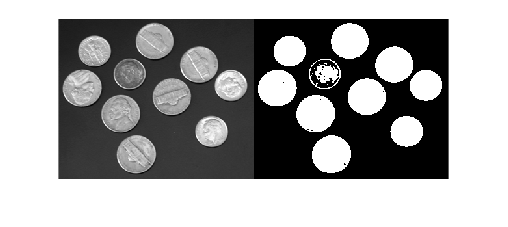

imshowpair(I,BW,'montage')

# Calculate Centroids and Superimpose Locations on Image

Read a binary image into workspace.

BW = imread('text.png');

Calculate centroids for connected components in the image using `regionprops`. The `regionprops` function returns the centroids in a structure array.

s = regionprops(BW,'centroid');

Store the *x*- and *y*-coordinates of the centroids into a two-column matrix.

centroids = cat(1,s.Centroid);

Display the binary image with the centroid locations superimposed.

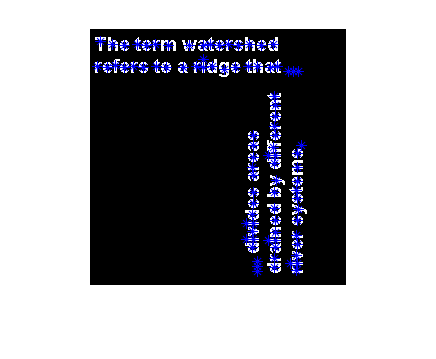

imshow(BW)
hold on
plot(centroids(:,1),centroids(:,2),'b*')
hold off

*Copyright 2015 The MathWorks, Inc.*

# Label Components Using 4-connected Objects

Create a small binary image.

BW = logical ([1     1     1     0     0     0     0     0
               1     1     1     0     1     1     0     0
               1     1     1     0     1     1     0     0
               1     1     1     0     0     0     1     0
               1     1     1     0     0     0     1     0
               1     1     1     0     0     0     1     0
               1     1     1     0     0     1     1     0
               1     1     1     0     0     0     0     0]);

Create the label matrix using 4-connected objects.

L = bwlabel(BW,4)

L =      1     1     1     0     0     0     0     0
     1     1     1     0     2     2     0     0
     1     1     1     0     2     2     0     0
     1     1     1     0     0     0     3     0
     1     1     1     0     0     0     3     0
     1     1     1     0     0     0     3     0
     1     1     1     0     0     3     3     0
     1     1     1     0     0     0     0     0


Use the `find` command to get the row and column coordinates of the object labeled "2".

[r, c] = find(L==2);
rc = [r c]

rc =      2     5
     3     5
     2     6
     3     6


*Copyright 2015 The MathWorks, Inc.*

# Calculate Area of Objects in Binary Image

Read a binary image and display it.

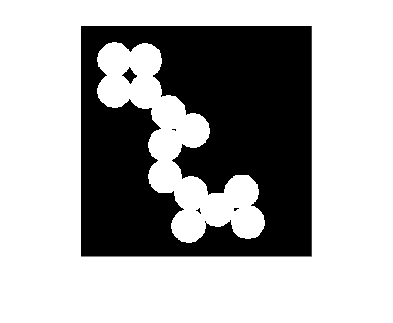

BW = imread('circles.png');
imshow(BW)

Calculate the area of objects in the image.

bwarea(BW)

ans = 1.4187e+04

*Copyright 2017 The MathWorks, Inc.*

# Select Objects in Binary Image

Select objects in a binary image and create a new image containing only those objects.

Read binary image into the workspace.

BW = imread('text.png');

Specify the locations of objects in the image using row and column indices.

c = [43 185 212];
r = [38 68 181];

Create a new binary image containing only the selected objects. This example specifies 4-connected objects. 

BW2 = bwselect(BW,c,r,4);

Display the original image and the new image side-by-side.

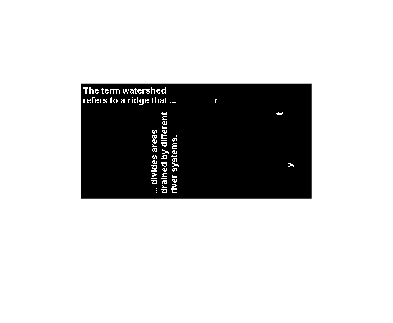

imshowpair(BW,BW2,'montage');

*Copyright 2015 The MathWorks, Inc.*

# Truth Table

Create a truth table for the logical AND operation. 

A = uint8([0 1; 0 1]);
B = uint8([0 0; 1 1]);
TTable = bitand(A, B)

TTable = 2×2 uint8 matrix
   0   0
   0   1


`bitand` returns 1 only if both bit-wise inputs are 1. 

*Copyright 2012 The MathWorks, Inc.*

# Truth Table

Create a truth table for the logical OR operation. 

A = uint8([0 1; 0 1]);
B = uint8([0 0; 1 1]);
TTable = bitor(A, B)

TTable = 2×2 uint8 matrix
   0   1
   1   1


`bitor` returns 1 if either bit-wise input is 1. 

*Copyright 2012 The MathWorks, Inc.*

# Truth Table

Create a truth table for the logical XOR operation. 

A = uint8([0 1; 0 1]);
B = uint8([0 0; 1 1]);
TTable = bitxor(A, B)

TTable = 2×2 uint8 matrix
   0   1
   1   0


`bitxor` returns 0 if both bit-wise inputs are equal. 

*Copyright 2012 The MathWorks, Inc.*

# Complement of a Negative Integer

A = int8(-11);
cmp = bitcmp(A);

You can see the complement operation when the numbers are shown in binary. 

original = bitget(A,8:-1:1)

original = 1×8 int8 row vector
   1   1   1   1   0   1   0   1


complement = bitget(bitcmp(A),8:-1:1)

complement = 1×8 int8 row vector
   0   0   0   0   1   0   1   0


*Copyright 2012 The MathWorks, Inc.*

## *q2*

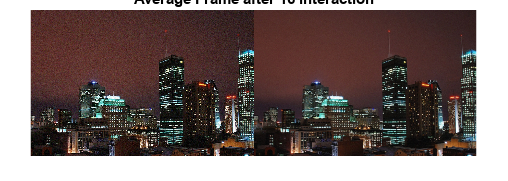

vidobj = VideoReader('Weather_Cam.avi');
numFrames = get(vidobj, 'NumberOfFrames');
Frame_Avrg=im2double(read(vidobj,1));
N_avg=16;
for i=2:N_avg
Frame=im2double(read(vidobj, i));
Frame_Avrg= Frame_Avrg+Frame;
end
Frame_Avrg= Frame_Avrg/N_avg;
figure
montage({Frame,Frame_Avrg})
title('Average Frame after 16 interaction');

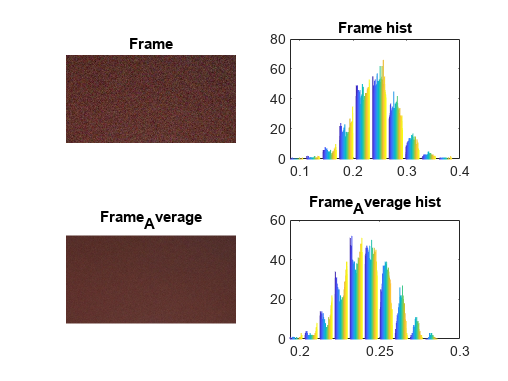

%rect = imrect;
%position = wait(rect);
position = [53 44 258 133];
roi1 = imcrop(Frame, position);
roi2 = imcrop(Frame_Avrg, position);
figure;
subplot(2,2,1);
imshow(roi1);title("Frame");
gray_roi1 = rgb2gray(roi1);
subplot(2,2,3);
imshow(roi2);title("Frame_Average");
gray_roi2 = rgb2gray(roi2);
subplot(2,2,2);
hist(gray_roi1);title("Frame hist");
subplot(2,2,4);
hist(gray_roi2);title("Frame_Average hist");

## Q3

figure;
frame=rgb2gray(Frame_Avrg);
dx=-4; %pixels
dy=-4; %pixels
theta = -3;
tform = affine2d([ ...
cosd(theta) sind(theta) 0;...
-sind(theta) cosd(theta) 0; ...
dx dy 1])

tform =   affine2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


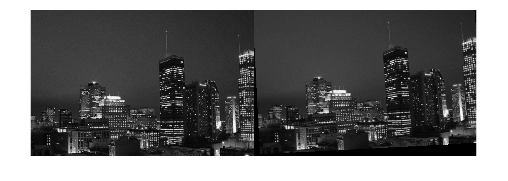

OutputView = affineOutputView(size(frame),tform,'BoundsStyle','sameAsInput');
Gframe = imwarp(frame,tform, 'FillValues',0,'OutputView',OutputView);
montage({frame,Gframe});

## Q4

# Create 2-D Affine Transformation

Define a 3-by-3 geometric transformation matrix. This example specifies a matrix for an affine transformation consisting of vertical shear and horizontal stretch.

A = [2 0 0; 0.33 1 0; 0 0 1];
tform = affinetform2d(A)

tform =   affinetform2d with properties:

    Dimensionality: 2
                 A: [3×3 double]


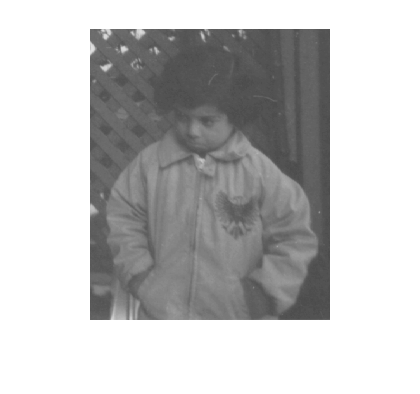

I = imread("pout.tif");
imshow(I)

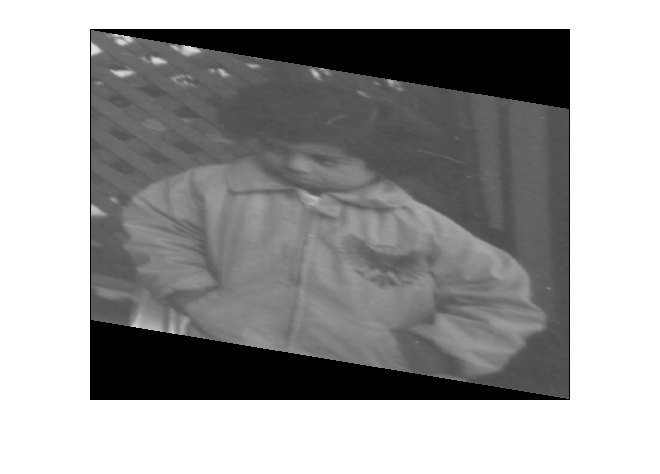

J = imwarp(I,tform);
imshow(J);

# Apply Horizontal Shear to Image

Read and display a grayscale image.

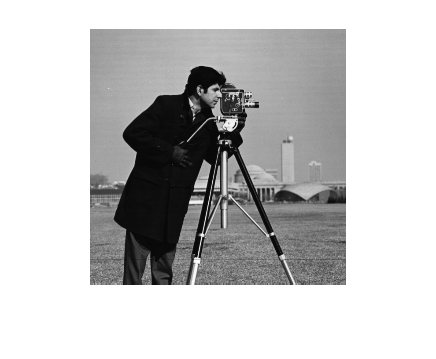

I = imread('cameraman.tif');
imshow(I)

Create a 2-D affine transformation.

A = [1 0.5 0; 0 1 0; 0 0 1];
tform = affinetform2d(A);

Apply the transformation to the image.

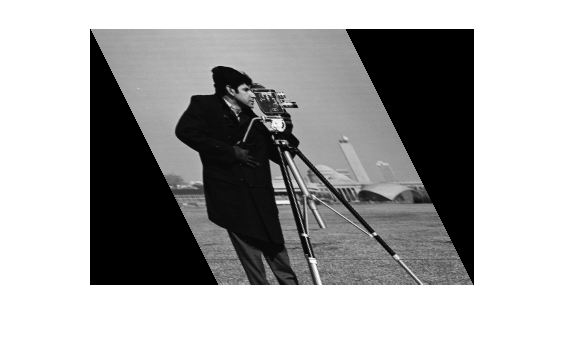

J = imwarp(I,tform);
imshow(J)

*Copyright 2015-2022 The MathWorks, Inc.*

# Warp Image Using Different Output View Styles

Read and display an image. To see the spatial extents of the image, make the axes visible.

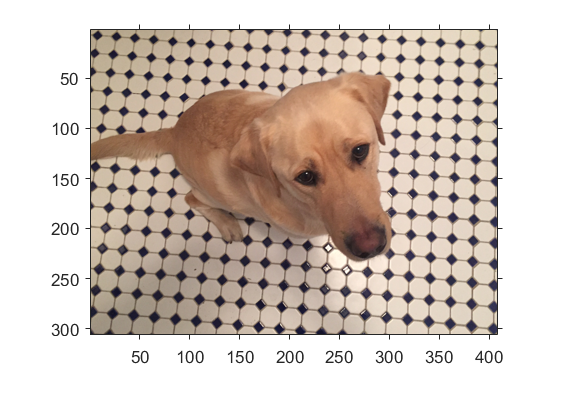

A = imread("kobi.png");
A = imresize(A,0.25);
iptsetpref("ImshowAxesVisible","on")
imshow(A)

Create a 2-D affine transformation. This example creates a randomized transformation that consists of scale by a factor in the range [1.2, 2.4], rotation by an angle in the range [-45, 45] degrees, and horizontal translation by a distance in the range [100, 200] pixels.

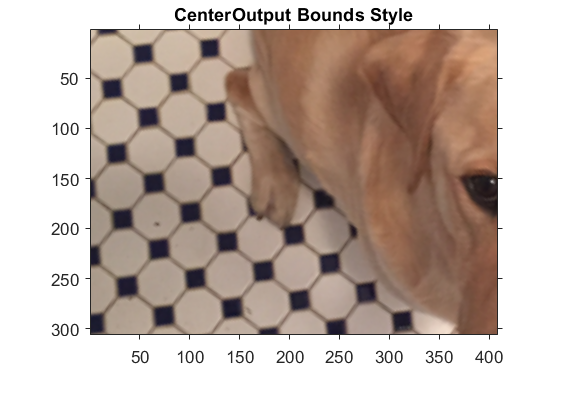

tform = randomAffine2d("Scale",[1.2,2.4],"XTranslation",[100 200],"Rotation",[-45,45]);
centerOutput = affineOutputView(size(A),tform,"BoundsStyle","CenterOutput");
followOutput = affineOutputView(size(A),tform,"BoundsStyle","FollowOutput");
sameAsInput = affineOutputView(size(A),tform,"BoundsStyle","SameAsInput");
BCenterOutput = imwarp(A,tform,"OutputView",centerOutput);
BFollowOutput = imwarp(A,tform,"OutputView",followOutput);
BSameAsInput = imwarp(A,tform,"OutputView",sameAsInput);
imshow(BCenterOutput)
title("CenterOutput Bounds Style");

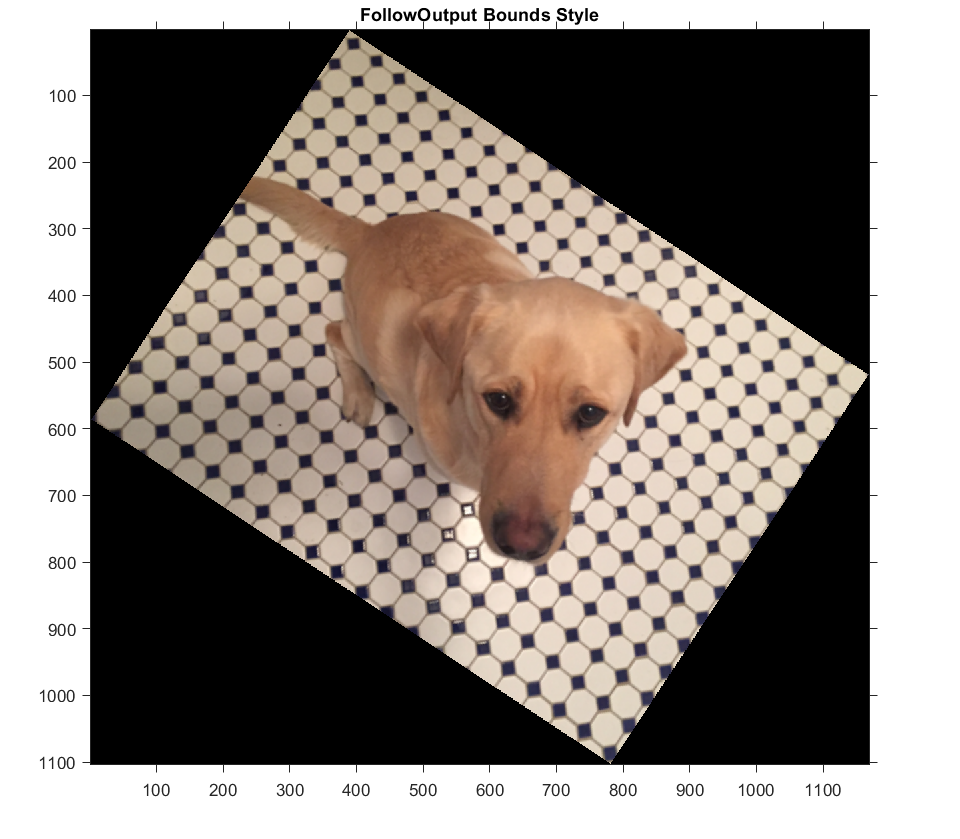

imshow(BFollowOutput)
title("FollowOutput Bounds Style");

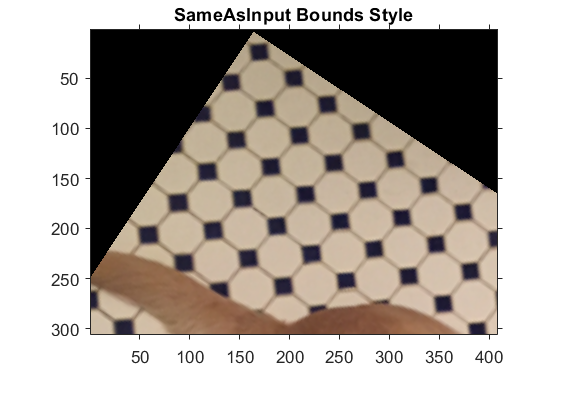

imshow(BSameAsInput)
title("SameAsInput Bounds Style");

iptsetpref("ImshowAxesVisible","off")

*Copyright 2019 The MathWorks, Inc.*